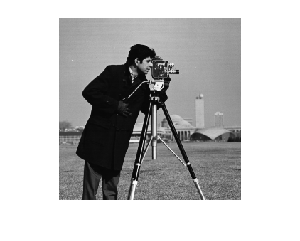

clear all;
clc;
 
input = imread('cameraman.tif');
imshow(input)

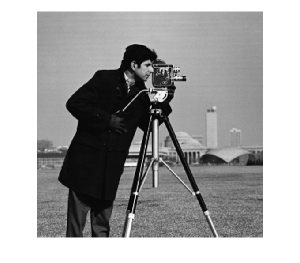

% Resize the image to required size
input=imresize(input, [512 512]);
imshow(input)

% Secret Message to be embedded
message='I am Aditya';

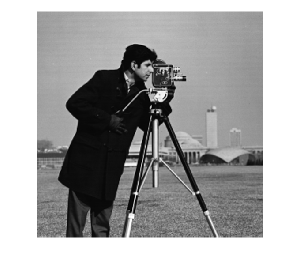

% Length of the message where each character is 8 bits
len = length(message) * 8;
 
% Get all the ASCII values of the characters of the message
ascii_value = uint8(message);
 
% Convert the decimal values to binary
bin_message = transpose(dec2bin(ascii_value, 8));
 
% Get all the binary digits in separate row
bin_message = bin_message(:);
 
% Length of the binary message
N = length(bin_message);
 
% Converting the char array to numeric array
bin_num_message= str2num(bin_message);
 
% Initialize output as input
output = input;
 
% Get height and width for traversing through the image
height = size(input, 1);
width = size(input, 2);
 
% Counter for number of embedded bits
embed_counter = 1;
 
% Traverse through the image
for i = 1 : height
    for j = 1 : width
         
        % If more bits are remaining to embed
        if(embed_counter <= len)
             
            % Finding the Least Significant Bit of the current pixel
            LSB = mod(double(input(i, j)), 2);
             
            % Find whether the bit is same or needs to change
            temp = double(xor(LSB, bin_num_message(embed_counter)));
             
            % Updating the output to input + temp
            output(i, j) = input(i, j)+temp;
             
            % Increment the embed counter
            embed_counter = embed_counter+1;
        end
         
    end
end

imshow(output)

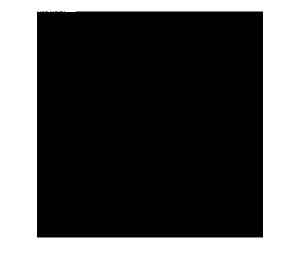

imshow((output-input)*10000) 

% Initialize a variable to store the extracted binary message
extracted_bin_message = '';

% Initialize a counter to keep track of the number of extracted bits
extract_counter = 1;

% Traverse through the image
for i = 1 : height
    for j = 1 : width
        % If more bits can be extracted
        if (extract_counter <= len)
            % Extract the LSB of the current pixel
            LSB = mod(double(output(i, j)), 2);
            
            % Append the extracted bit to the binary message
            extracted_bin_message = [extracted_bin_message, num2str(LSB)];
            
            % Increment the extract counter
            extract_counter = extract_counter + 1;
        else
            break;  % All bits have been extracted, exit the loop
        end
    end
    if (extract_counter > len)
        break;  % All bits have been extracted, exit the loop
    end
end

% Convert the binary message back to text
extracted_ascii_values = reshape(extracted_bin_message, 8, []).';
extracted_decimal_values = bin2dec(extracted_ascii_values);

% Concatenate the extracted decimal values into a single string
extracted_message = char(extracted_decimal_values)';

% Display the extracted message
disp(extracted_message);

I am Aditya
